# Integrated ORP-HTL Model (Single County) - SENSITIVITY ANALYSIS

This live script is used to run the integrated microalgae model. The modules within the integrated model include:

- **Thermal Model:** Determines pond temperatures and evaporation with hourly resolution in the location of interest

- **Growth Model: **Determines the microalgae growth rate with hourly resolution in the location of interest

- **Cultivation and Dewatering Model:** Determines energy consumption for pumps and paddlewheels, consumption of ammonia, DAP, and CO2, blue and green water footprint, and the net biomass output from cultivation in Open Raceway Ponds (ORPs) with a 3-stage dewatering process (bioflocculation, membrane separation, and centrifugation)

- **Storage Model:** Determines additional requirements for long-term (6+ months) anaerobic biomass storage to offset seasonal production variability, storage losses, and the resulting biomass composition sent to fuel conversion

- **HTL and Fuel Upgrading Model: **Determines energy and consumables for Hydrothermal Liquefaction (HTL) to convert algae biomass into biocrude, energy and consumables for fuel upgrading via hydrotreating and hydrocracking to produce renewable diesel and naphtha from biocrude, and the resulting annual fuel output based on biomass composition and reactor configuration

- **Techno-Economic Analysis (TEA): **Determines the total capital expenditure and annual operational expenses for the integrated biorefinery and solves for the minimum fuel and minimum biomass selling prices using a 30-year discounted cash flow rate of return (DCFROR) analysis with standard Nth-plant economic assumptions

- **Life Cycle Assessment (LCA):** Determines the life cycle environmental impacts of the integrated biorefinery across all 10 impact categories from the Tool for the Reduction and Assessment of Chemical and other environmental Impacts (TRACI 2.1), and total freshwater consumption 

## Step 1: Define Inputs for the Process Model

While some of the model inputs are adjustable by the user, many inputs are built into the model to increase ease-of-use and ensure accurate reporting. The adjustable inputs are defined by the use below:

### 1.1 Facility Location:

clear
clc
load background_data.mat county_dat
states_val = unique(county_dat(:,4));
State = states_val(42);
states_indx = find(strcmp(county_dat(:,4),State));
county_val = unique(county_dat(states_indx,3)); 

try
County = county_val(235);
catch
County = county_val(1);
end

% Weather file path
[file_ids,weather_script,coords] = weather_finder(County,State);

% Parse weather
T_amb= (weather_script(:,4)); % ambient temperature deg C
RH= weather_script(:,5); % relative humidity (%)
WNDSPD= weather_script(:,3); % wind speed (m per sec)
GHI= weather_script(:,2); % GHI (W per m2) 

Rainfall = "Off";
    if Rainfall == "On"
    rainfall_mat = weather_script(:,6)/1000; % m per hr, hourly average
    else 
    rainfall_mat = zeros(8760,1);
    end 

Value = [County; max(weather_script(:,1)); mean(T_amb); mean(RH); (sum(GHI)/max(weather_script(:,1)))/1000; (sum(rainfall_mat)/max(weather_script(:,1)))*100/2.54];
fprintf('Average Weather Parameters for %s County (Average of %.0f Weather Stations)  \nAverage Ambient Temperature = %.1f degrees C \nAverage Relative Humidity = %.0f%% \nTotal Global Horizonatl Irradiance (GHI) = %.1f kWh/m2 \nTotal Annual Rainfall = %.1f inches \n', Value);

Average Weather Parameters for Zapata County (Average of 1 Weather Stations)  
Average Ambient Temperature = 24.7 degrees C 
Average Relative Humidity = 63% 
Total Global Horizonatl Irradiance (GHI) = 1950.3 kWh/m2 
Total Annual Rainfall = 0.0 inches 


### 1.2 Facility Size and Layout:

Select the facility size in total wetted acres and specify the size of individual ponds. Expect the MBSP and MFSP to increase significantly with facility sizes smaller than 5000 wetted-acres due to economies of scale.

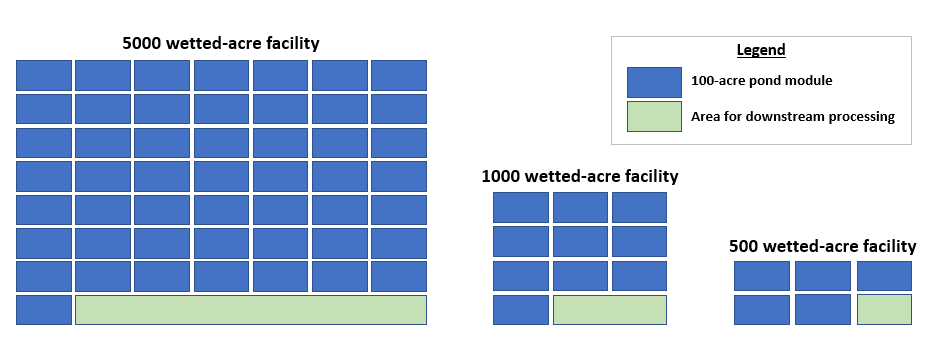

wetted_acres = 5000; % wetted-acres
pond_size = 10; % acres
depth = 0.2; % m
max_depth = 0.25*100; % enter in m, converted to cm
min_depth = 0.15*100; % enter in m, converted to cm

*"Max Pond Depth" must be greater than "Pond Depth" and "Min Pond Depth" must be less than "Pond Depth" specified above. When heavy rainfall ocurrs, the model may "break" if the the pond must be drained below the minimum specified depth. If rainfall is "On," the minimum pond depth should be set very low (0.01 - 0.05 m) to avoid issues with pond volume and harvesting.  *

% Facility Size and Layout 
num_ponds = ceil(wetted_acres/pond_size);
module_size = 100; % wetted-acres (fixed)
    if pond_size == 10
        if wetted_acres == 5000
            length_orp = 2*670*7; % m --> module is 2 ponds wide (670 m length per pond); Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        else 
            length_orp = 2*670*3; % m --> total length for 5000 wetted acres with 10-acre ponds is 10070.4 m in Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        end 
    else 
        if wetted_acres == 5000
            length_orp = 4*417*7; % m --> module is 2 ponds wide (670 m length per pond); Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        else 
            length_orp = 4*417*3; % m --> total length for 5000 wetted acres with 10-acre ponds is 10070.4 m in Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        end 
    end 

% Model Input Vectors 
geom_vec = [length_orp width depth max_depth min_depth] ;

### 1.3 Harvesting Sequence:

Define harvesting parameters for the cultivation facility including the pond inoculation concentration, the concentration at which harvesting is triggered, and maximum days between automated harvesting events (regardless of pond concentration). If "Rainfall" is turned on, harvesting is also triggered when rainfall causes the pond depth to exceed the maximum allowable depth specified above. *Please note the harvesting concentration must be greater than the inoculation concentration.*

% Harvest sequence, concentrations in gpL and days to harvest
CX_inoculation = 0.1*1000; % entered as gpL and converted to g/m3
CX_harvesting = 0.6*1000; % entered as gpL and converted to g/m3
harv_days = 5; % days until automated harvest cycle is triggered

%Build model input vectors
harvest_vec = [CX_inoculation CX_harvesting harv_days 250 4000]; %[initial_CX final_CX days_to_harvest i_salt salt_max_cx]
sensitivity_inputs(1:5,1) = harvest_vec; 

strain = "S_obliquus"; 
strain_vec =[305.4, 276.2, 314.1, 0.38, 480, 0.03, 1.5]; %[max temp, min temp, optimal temp, ODC, sat light intensity, dark respiration losses, phi] - phi is photon efficiency of 12 g biomass/8 mol photons = 1.5

### 1.4 Nutrients and CO2 Consumption Parameters:

Define the C, N, and P content of the microalgae to quantify the consumption of ammonia, DAP, and CO2 used for cultivation. *Please enter percentages as fractions (for example, 25% is entered as 0.25).*

**    Carbon Content and Carbon Utilization and Capture Efficiencies:**

c_content = 0.574; % ash-free dry weight basis 
sparge_eff =  0.9;
sensitivity_inputs(6,1) = sparge_eff; 

%Optional inputs to include CO2 capture energy and emissions in boundary
CO2_capture_elec_en = 0; %MJ elec/tCO2 captured supplied by local grid
CO2_capture_therm_en = 0;  %MJ thermal/tCO2 captured supplied by NG - enter 0 and include emissions from thermal energy gen. in indirect emissions when using waste heat 
CO2_capture_indir_GHG = 0;  %GHG from CO2 capture consumables (MEA, water, other chemicals, sorbents, solvents, etc.) - will vary based on CO2 capture tech.

%Build model input vectors
co2_capt_lci = [CO2_capture_indir_GHG; CO2_capture_therm_en; CO2_capture_elec_en];

**    N + P Content in Algae and Nutrients:**

rep_dep = "Nutrient Replete";
p_content = 0.002; % ash-free dry weight basis
n_content = 0.016; % ash-free dry weight basis
p_content_dap = 0.2; % dw basis
n_content_dap = 0.18; % dw basis
n_content_ammonia = 0.82; % dw basis
sensitivity_inputs(7:8,1) = [p_content; n_content]; 

    switch rep_dep
        case 'Nutrient Replete'
        nutrient_surpluss = 0.2; % percentage surplus of nutrients supplied
        case 'Nutrient Deplete'
        nutrient_surpluss = 0.0; % percentage surplus of nutrients supplied 
    end 

**Transportation distances for Ammonia:**

% Ecoinvent default: 276 km by freight train, 47 km by freight-inland waterways, 148 km  by freigh lorry-unspecified, 
% 841 km by sea container ship - transportation distances in km
ammonia_transp_lorry = 148;
ammonia_transp_train = 276;
ammonia_transp_inland_ww = 47;
ammonia_transp_sea_container = 841;

**Transportation Distances for DAP:**

% Ecoinvent default: 276 km by freight train, 47 km by freight-inland waterways, 148 km  by freigh lorry-unspecified, 
% 841 km by sea container ship - transportation distances in km
DAP_transp_lorry = 148;
DAP_transp_train = 276;
DAP_transp_inland_ww = 47;
DAP_transp_sea_container = 841;

transp_vec = [ammonia_transp_train, ammonia_transp_inland_ww, ammonia_transp_lorry, ammonia_transp_sea_container; % ammonia
              DAP_transp_train, DAP_transp_inland_ww, DAP_transp_lorry, DAP_transp_sea_container]; % DAP

### 1.5 Inputs for Composition and Anaerobic Storage:

**Microalgae Composition (dry weight basis):**

*Please note the algae composition must sum to 100% (proteins + carbohydrates + lipids + ash = 100%).*

prot = 0.09; % dry wt%
carb = 0.421; % dry wt%
lip = 0.412; % dry wt%
ash = 0.077; % dry wt%

sum_comp = (prot + carb + lip + ash)*100;
fprintf('Current Sum = %0.2f %%', sum_comp);

Current Sum = 100.00 %

**Anaerobic Storage Parameters:**

degradation = 0.05; % dry matter lost to acid formation - based on Wendt et al., 2019 (INL)
centr_out_dens = 1042; %kg/m3 - Li et al., 2020
pump_eff = 0.7; % pumping efficiency
sensitivity_inputs(9:10,1) = [degradation; pump_eff];

% Build comp_vector now that all parameters are defined
comp_vector = [c_content sparge_eff p_content p_content_dap n_content_dap n_content n_content_ammonia nutrient_surpluss ash];

### 1.6 Inputs for Hydrothermal Liquefaction (HTL) and Fuel Upgrading

The composition of the microalgae can significantly impact HTL performance. The composition (as harvested) is defined above under "Microalgae Composition (dry weight basis)" and to evaluate HTL performance for locations where seasonal variability is minimal or will not be considered, storage losses can be set to 0% to represent this scenario.

annual_uptime = 330; % days per year in full operation
res_time = 15; % minutes
sensitivity_inputs(11,1) = annual_uptime; 

% Additional Inputs Required to Run HTL Module
fac_size = wetted_acres; 
reactor_diam = 0.667; %ft (8 inches) - Chen et al., 2021

Char_recovery = 0.9; % percent of HTL solids (char) recovered and sold as biochar co-product 
NH3EQ_recovery = 0.9; % of NH3 exiting HTL recovered from the aqueous phase
DAPEQ_recovery = 0.9; % of DAP exiting HTL recovered from the aqueous phase
sensitivity_inputs(12:14,1) = [Char_recovery; NH3EQ_recovery; DAPEQ_recovery]; 

### 1.7 Inputs for the Techno-Economic Analysis

Use this section to define commodity prices such as ammonia, DAP, electricity, and CO2 and to define critical assumptions for the cash flow analysis.

**Assumptions for the Discounted Cash Flow Rate of Return Model:**

Cost_year = 2019; % cost year used to adjust CAPEX and OPEX
IRR = 0.1; % Internal Rate of Return in DCFROR 
sensitivity_inputs(15,1) = IRR;

**Commodity Prices and Transportation Distances:**

*Default commodity prices are reported in 2019 dollars. Enter commodity prices in 2019 dollars and all costs are indexed within the model to the "Cost Year" entered above.*

Cultivation Consumables:

%Commodity prices
Elec_cost = 0.07; % 2019$/kWh - EIA (2019)
CO2_cost = 50; % $/tCO2
ammonia_cost = 0.8; % $/kg in 2019 USD (from $0.39/lb in 2011 dollars - Davis et al.)
dap_cost = 0.66; % $/kg in 2019 USD (from $0.32/lb in 2011 dollars - Davis et al.)

HTL and Upgrading Consumables:

NG_cost = 0.2154; % 2011$/kg - $5.10/1000 scf - Dutta et al., 2011; indexed to 2019 dollars
H_cost = 1.47; % 2012$/kg - Dilich et al., 2012; indexed to 2019 dollars
Process_water_cost = 0.204/1000; % $/m3 converted to $/kg - 2011$/kg - Dutta et al., 2011; indexed to 2019 dollars
NH3EQ_value = 0.8; % $/kg in 2019 USD (from $0.39/lb in 2011 dollars - Davis et al.)
DAPEQ_value = 0.66; % $/kg in 2019 USD (from $0.32/lb in 2011 dollars - Davis et al.)
Char_value = 0.1; % 2019$/kg - Assumption

% Critical Inputs Cost Matrix
cost_matrix = [Elec_cost, ammonia_cost, dap_cost, CO2_cost]; %$/kWh, $/kg ammonia, $/kg DAP, $/tCO2
sensitivity_inputs(16:19,1) = cost_matrix';
sensitivity_inputs(20:25,1) = [NG_cost; H_cost; Process_water_cost; NH3EQ_value; DAPEQ_value; Char_value]; 

## 1.9 Sensitivity Analysis Percent

sens_percent = 20/100; 

## Step 2: Run the Model with the Current Inputs

 

% Set up the analysis
sens_outputs = zeros(size(sensitivity_inputs,1),18); 

% Build sensitivity variable table
sensitivity_inputs(:,2) = sensitivity_inputs(:,1).*(1+sens_percent); % Increased value
sensitivity_inputs(:,3) = sensitivity_inputs(:,1).*(1-sens_percent); % Decreased value

% Adjust and correct for limits on days and percentages
sensitivity_inputs(3,2) = sensitivity_inputs(3,1)+1; % Increased value - harvest days
sensitivity_inputs(3,3) = sensitivity_inputs(3,1)-1; % Decreased value - harvest days
    
    if sensitivity_inputs(6,2) > 1
        sensitivity_inputs(6,2) = 1; % CUE
    end
    
    if sensitivity_inputs(10,2) > 1
        sensitivity_inputs(10,2) = 1; % Storage Pump Eff. 
    end
    
    if sensitivity_inputs(11,2) > 365
        sensitivity_inputs(11,2) = 365; % Op days
    end
    
    if sensitivity_inputs(12,2) > 1
        sensitivity_inputs(12,2) = 1; % Char Recovery
    end

    if sensitivity_inputs(13,2) > 1
        sensitivity_inputs(13,2) = 1; % NH3 Recovery
    end
    
    if sensitivity_inputs(14,2) > 1
        sensitivity_inputs(14,2) = 1; % DAP Recovery
    end

for j = 1:size(sensitivity_inputs,1)
    sens_inputs = sensitivity_inputs(:,1); % set all to baseline value
    
    for k = 1:3 % 3
        sens_inputs(j,1) = sensitivity_inputs(j,k); % adjust one variable at a time
        
        %Assign sensitivity variables to input values
        harvest_vec = sens_inputs(1:5,1)'; 
        sparge_eff = sens_inputs(6,1);
        p_content = sens_inputs(7,1);  
        n_content = sens_inputs(8,1); 
        comp_vector = [c_content sparge_eff p_content p_content_dap n_content_dap n_content n_content_ammonia nutrient_surpluss ash];
        degradation = sens_inputs(9,1);
        pump_eff = sens_inputs(10,1);
        annual_uptime = sens_inputs(11,1);
        Char_recovery = sens_inputs(12,1);
        NH3EQ_recovery = sens_inputs(13,1);
        DAPEQ_recovery = sens_inputs(14,1);
        IRR = sens_inputs(15,1);
        cost_matrix = sens_inputs(16:19,1)'; 
        NG_cost = sens_inputs(20,1); 
        H_cost = sens_inputs(21,1); 
        Process_water_cost = sens_inputs(22,1); 
        NH3EQ_value = sens_inputs(23,1); 
        DAPEQ_value = sens_inputs(24,1); 
        Char_value = sens_inputs(25,1); 
        sens_var_names = ["Innoculation Conc.";	"Harvest Conc."; "Harvest Days"; "Initial Salt Conc."; "Max Salt Conc.";
        	"CUE"; "P Content Algae"; "N Content Algae"; "Storage Losses"; "Slurry Pump Eff."; "Op Days";
            "Char Recovery"; "NH3 Recovery"; "DAP Recovery"; 
        	"IRR"; "Elec. Cost"; "Ammonia Cost"; "DAP Cost"; "CO2 Cost"; "NG Cost"; "H2 Cost";
        	"Water Cost"; "NH3 Value"; "DAP Value"; "Char Value"];

% Run the thermal, cultivation, and dewatering models to get critical
% outputs used in the HTL and upgrading functions

%paramters used in optimization that are not used here
prod_scale = 1;
nut_rem = 0; 
rec_P = 0;
grid_red = 0; 

% Pre-allocate output variables
Cult_Out_Station_D = zeros(26, size(coords,1));
HTL_process_mod_out_D = zeros(25, size(coords,1)); 
pond_temps_mat = zeros(4, size(coords,1)); 
cult_TEA_out_CAPEX_D = zeros(61,size(coords,1)); 
cult_TEA_out_OPEX_D = zeros(9,size(coords,1));
HTL_UG_CAPX_OPX_D = zeros(64, size(coords,1)); 
storage_fcn_out_D = zeros(12, size(coords,1)); 
MBSP = zeros(size(coords,1),1); 
MFSP = zeros(size(coords,1),1);
aware_cult_1_D = zeros(size(coords,1), 13);
aware_cult_2_D = zeros(size(coords,1), 13); 
cash_flow_mbsp_3D = zeros(33, 24, size(coords,1)); 
cash_flow_mfsp_3D = zeros(33, 24, size(coords,1)); 
bC_HTL_gas_D = zeros(1,size(coords,1));

for i = 1:size(coords,1) 
    weather_input = weather_script(weather_script(:,1) == i, [4,5,2,3]);
    T_amb = weather_script(weather_script(:,1) == i, 4);
    RH = weather_script(weather_script(:,1) == i, 5);
    GHI = weather_script(weather_script(:,1) == i, 2);
    WNDSPD = weather_script(weather_script(:,1) == i, 3);
    
    if Rainfall == "On"
    rainfall_mat = weather_script(weather_script(:,1) == i, 6)/1000; % m per hr, hourly average
    else 
    rainfall_mat = zeros(8760,1);
    end 
    
    % Thermal Model
    [TR,evap_rate, Water_con, M_Evap] = thermal_fcnV6(weather_input,geom_vec); 
   
    % Thermal Model Outputs
    annual_evap_cm_day = evap_rate(1,5);
    pond_temps_mat(:,i) = [max(TR)-273.15; min(TR)-273.15; mean(TR)-273.15; annual_evap_cm_day];
    
    % Cultivation and Storage Functions
    [CX, centr_out, centr_out_ann, cult_out, water_vol, CO2_demand_hourly,aquifer_hrly, area, total_recycled, num_settling_ponds, settlers_out, membrane_out,aware_cult, nutrients, recycled_membr_centr, dep_rep_scaling, harvest_water, Conc_at_Harvest, light_eff_track, aquifer, rec_algae, biomass_balance, energy_balance, dewatering_mat, check_biomass] = cultivation_fcn([TR GHI M_Evap rainfall_mat],geom_vec,strain_vec, harvest_vec, comp_vector, rep_dep, prod_scale, carb, lip, prot);
    [storage_fcn_out, ann_ave_centr, biomass_balance_st, comp_ann_ave_centr] = Storage_fcn(prot, carb, lip, ash, centr_out, centr_out_dens, degradation, pump_eff);
    
        % Protein extraction and value recovery
        if rec_P > 0
    
        protein_out_storage = biomass_balance_st(2,3); %kg protein per year
        protein_diverted = rec_P*protein_out_storage; %kg protein/yr diverted and recovered
        protein_value = 5; %dollars per kg protein product
        protein_revenue = protein_diverted*protein_value; % $5/kg per kg protein diverted and recovered as annual revenue
        
        ann_ave_centr = (ann_ave_centr*8760 - protein_diverted)/8760; %kg/hr - protein diverted (kg/hr)
        
        conv_feed_prot =  protein_out_storage*(1-rec_P); 
        conv_feed_carb = biomass_balance_st(3,3); 
        conv_feed_lip = biomass_balance_st(4,3); 
        conv_feed_ash = biomass_balance_st(5,3); 
        conv_feed_total = conv_feed_prot + conv_feed_carb + conv_feed_lip + conv_feed_ash; % kg DW/hr (includes ash)
        
        prot_n = conv_feed_prot/conv_feed_total; 
        carb_n = conv_feed_carb/conv_feed_total; 
        lip_n = conv_feed_lip/conv_feed_total; 
        ash_n = conv_feed_ash/conv_feed_total; 
    
        water_in = ann_ave_centr*8760*0.80; %total kg water in = water out
        AFDW_out = conv_feed_prot + conv_feed_carb + conv_feed_lip;
        ppe_TSS = AFDW_out/(AFDW_out + water_in); 
          
        %Mass balance for protein extraction
        biomass_balance_PE(1,1) = protein_diverted;
        biomass_balance_PE(2,1) = protein_diverted;
        biomass_balance_PE(3,1) = 0;
        biomass_balance_PE(4,1) = 0;
        biomass_balance_PE(5,1) = 0;
        
        biomass_balance_PE(1,2) = conv_feed_total;
        biomass_balance_PE(2,2) = conv_feed_prot;
        biomass_balance_PE(3,2) = conv_feed_carb;
        biomass_balance_PE(4,2) = conv_feed_lip;
        biomass_balance_PE(5,2) = conv_feed_ash;
    
        % Biomass mass balance between cultivation, dewatering, storage and protein extraction
        comp_biomass_balance = [biomass_balance biomass_balance_st biomass_balance_PE]; 
        
        % Outputs to conversion 
        algae_comp_to_con = [prot_n; carb_n; lip_n; ash_n; ppe_TSS]; 
        
        else 
        %Protein revenue is zero
        protein_revenue = 0; 

        % Biomass mass balance between cultivation, dewatering, storage
        comp_biomass_balance = [biomass_balance biomass_balance_st];
            
        % Composition and solids from storage - ps: post-storage
        prot_n = str2double(storage_fcn_out(3,2));
        carb_n = str2double(storage_fcn_out(4,2));
        lip_n = str2double(storage_fcn_out(5,2));
        ash_n = str2double(storage_fcn_out(6,2));
        TSS_n = str2double(storage_fcn_out(12,2));
    
        % Outupts to conversion
        algae_comp_to_con = [prot_n; carb_n; lip_n; ash_n; TSS_n];
    
        end

    % Areal Productivity Calcs at different stages
    areal_prod = str2double(cult_out(2,2)); %productivity calculated in cultivation function 
    areal_prod_adj = sum(centr_out)*0.20*1000/area/365; %productivity calculated using centr_out (after dewatering) - 20% solids is on an AFDW basis
    areal_prod_adj_st = ann_ave_centr*8760*0.20*1000/area/365; %productivity calculated using storage_fcn ann_ave_centr flow (including losses) - 20% solids is on an AFDW basis
    
    % Cultivation TEA Function
    [cult_TEA_out_CAPEX, cult_TEA_out_OPEX] = Cultivation_TEA_fcn(Cost_year, num_ponds, pond_size, module_size, CO2_demand_hourly, aquifer_hrly, total_recycled, storage_fcn_out, num_settling_ponds, settlers_out, membrane_out, cult_out, cost_matrix, recycled_membr_centr, nut_rem);

    % HTL and Upgrading Model
    [HTL_process_mod_out, HTL_UG_CAPX_OPX, direct_cap, case_number, biogenic_c_in_gas_phase] = HTL_and_UG_fcn(prot_n, carb_n, lip_n, ash_n , areal_prod_adj_st, fac_size, res_time, reactor_diam, annual_uptime, Char_recovery, NH3EQ_recovery, DAPEQ_recovery, Cost_year, NG_cost, H_cost, Elec_cost, Process_water_cost, NH3EQ_value, DAPEQ_value, Char_value, cult_out, nut_rem);
    
    % DCFROR for Minimum Bioass Selling Price
    total_tonnes_AFDW = str2double(cult_out(1,2)); %tonnes AFDW/yr
    land_CAPEX = str2double(cult_TEA_out_CAPEX(59,2));
    equip_fac_CAPEX = str2double(cult_TEA_out_CAPEX(58,2));
    working_CAPEX = 0.05*equip_fac_CAPEX; 
    total_OPEX = str2double(cult_TEA_out_OPEX(9,2)); 

    options = optimset('Display','off');

    fun = @NPV_MBSP;
    x0 = 1;
    MBSP(i,1) = fsolve(fun, x0, options, total_tonnes_AFDW, land_CAPEX, equip_fac_CAPEX, working_CAPEX, total_OPEX, IRR);
    [NPV, cash_flow] = NPV_MBSP(MBSP(i,1), total_tonnes_AFDW, land_CAPEX, equip_fac_CAPEX, working_CAPEX, total_OPEX, IRR);

    % DCFROR for Minimum Fuel Selling Price
    GGE_per_yr = str2double(HTL_process_mod_out(12,2)); %GGE/yr
    land_CAPEX = str2double(cult_TEA_out_CAPEX(59,2)); %from cultivation (includes area for downstream processing)
    total_equip_fac_CAPEX = str2double(cult_TEA_out_CAPEX(58,2)) + str2double(HTL_UG_CAPX_OPX(45,2));
    total_working_CAPEX = 0.05*total_equip_fac_CAPEX;
    total_combined_OPEX = str2double(cult_TEA_out_OPEX(9,2)) + str2double(HTL_UG_CAPX_OPX(53,2)) + str2double(HTL_UG_CAPX_OPX(64,2));
    total_coprod_rev = str2double(HTL_UG_CAPX_OPX(58,2));

    fun = @NPV_MFSP;
    x0 = 0.1;
    MFSP(i,1)= fsolve(fun, x0, options, GGE_per_yr, land_CAPEX, total_equip_fac_CAPEX, total_working_CAPEX, total_combined_OPEX, IRR, total_coprod_rev);
    [NPV_mfsp, cash_flow_mfsp] = NPV_MFSP(MFSP(i,1), GGE_per_yr, land_CAPEX, total_equip_fac_CAPEX, total_working_CAPEX, total_combined_OPEX, IRR, total_coprod_rev);
      
    % Combined Outputs (for each weather station)
    Cult_Out_Station_D(:,i) = cult_out(:,2); 
    HTL_process_mod_out_D(:,i) = HTL_process_mod_out(:,2);
    cult_TEA_out_CAPEX_D(:,i) = cult_TEA_out_CAPEX(:,2); 
    cult_TEA_out_OPEX_D(:,i) = cult_TEA_out_OPEX(:,2); 
    HTL_UG_CAPX_OPX_D(:,i) = HTL_UG_CAPX_OPX(:,2); 
    storage_fcn_out_D(:,i) = storage_fcn_out(:,2);
    cash_flow_mbsp_3D(:,:,i) = table2array(cash_flow); 
    cash_flow_mfsp_3D(:,:,i) = table2array(cash_flow_mfsp); 
    bC_HTL_gas_D(:,i) = biogenic_c_in_gas_phase; 

    % AWARE Cultivation Metrics
    aware_cult_1_D(i,:) = aware_cult(1,:);
    aware_cult_2_D(i,:) = aware_cult(2,:); 

end 
    
% LCA model uses outputs from cultivation model from all weather stations to find averaege LCA metrics for each County
[process_lca, stage_breakdwn,stage_breakdwn_prc, consum_breakdwn, consum_breakdwn_prc,wsf_monthly, traci_vec, cf_vec, nerc_out, bC_balance] = LCA_HTL_ext(co2_capt_lci,Cult_Out_Station_D,storage_fcn_out_D,HTL_process_mod_out_D,coords(i,:),direct_cap,file_ids{i}, aware_cult_1_D, aware_cult_2_D,transp_vec, annual_uptime, grid_red, bC_HTL_gas_D);
wsf_cult_D = wsf_monthly(13,1); % m3-eq/tonne AFDW
wsf_fuels_D = wsf_monthly(13,2); % m3-eq/MJ fuel

    % Sensitivity Output Data Matrix
    sens_outputs(j,1:3) = sensitivity_inputs(j,:); 
    sens_outputs(j,k+3) = mean(MBSP); 
    sens_outputs(j,k+6) = mean(MFSP); 
    sens_outputs(j,k+9) = process_lca(1,6)*1000; %gCO2-eq/MJ SAF
    sens_outputs(j,k+12) = process_lca(1,11)*1000; %m3/GJ

    end    
end 

sens_outputs_cell = num2cell(sens_outputs);
sens_outputs_combined = [sens_var_names sens_outputs_cell];

for i = 1:size(sens_outputs,1)
MBSP_max_delta(i,1) = max(abs((sens_outputs(i,5)-sens_outputs(i,4))), abs((sens_outputs(i,6)-sens_outputs(i,4)))); %#ok<SAGROW> 
MFSP_max_delta(i,1) = max(abs((sens_outputs(i,8)-sens_outputs(i,7))), abs((sens_outputs(i,9)-sens_outputs(i,7)))); %#ok<SAGROW> 
GWP_max_delta(i,1) = max(abs((sens_outputs(i,11)-sens_outputs(i,10))), abs((sens_outputs(i,12)-sens_outputs(i,10)))); %#ok<SAGROW> 
BWF_max_delta(i,1) = max(abs((sens_outputs(i,14)-sens_outputs(i,13))), abs((sens_outputs(i,15)-sens_outputs(i,13)))); %#ok<SAGROW> 
end 

% Build final sensitivity outputs
sens_out_MBSP = [sens_outputs_combined(:,1:7) num2cell(MBSP_max_delta)];
sens_out_MFSP = [sens_outputs_combined(:,[1:4, 8:10]) num2cell(MFSP_max_delta)];
sens_out_GWP = [sens_outputs_combined(:,[1:4, 11:13]) num2cell(GWP_max_delta)];
sens_out_BWF = [sens_outputs_combined(:,[1:4, 14:16]) num2cell(BWF_max_delta)];

% Convert the numeric parts for sorting while keeping names associated
sens_MBSP = str2double(sens_out_MBSP(:, 2:end));
sens_MFSP = str2double(sens_out_MFSP(:, 2:end));
sens_GWP = str2double(sens_out_GWP(:, 2:end));
sens_BWF = str2double(sens_out_BWF(:, 2:end));

% Sort based on the second column of the numeric data (original column 3)
[~, idx_MBSP] = sort(sens_MBSP(:, 7), 'ascend');
[~, idx_MFSP] = sort(sens_MFSP(:, 7), 'ascend');
[~, idx_GWP] = sort(sens_GWP(:, 7), 'ascend');
[~, idx_BWF] = sort(sens_BWF(:, 7), 'ascend');

% Apply the sorted index to the original cell array
MBSP_sens_sorted = sens_out_MBSP(idx_MBSP, :);
MFSP_sens_sorted = sens_out_MFSP(idx_MFSP, :);
GWP_sens_sorted = sens_out_GWP(idx_GWP, :);
BWF_sens_sorted = sens_out_BWF(idx_BWF, :);

## Step 4: Print Model Outputs to Excel

Print detailed model outputs to the pre-made Excel outputs sheet for data management and visualization.

*Note: The Excel outputs file "Single_Run_Outputs_HTL_v2_Sensitivity.xlsm" needs to be closed in order to print outputs.*

 
writematrix(MBSP_sens_sorted(:,1),'Single_Run_Outputs_HTL_v3_Sensitivity.xlsm','Sheet',1,'Range','A2:A26','AutoFitWidth',0);
writematrix(MFSP_sens_sorted(:,1),'Single_Run_Outputs_HTL_v3_Sensitivity.xlsm','Sheet',2,'Range','A2:A26','AutoFitWidth',0);
writematrix(GWP_sens_sorted(:,1),'Single_Run_Outputs_HTL_v3_Sensitivity.xlsm','Sheet',3,'Range','A2:A26','AutoFitWidth',0);
writematrix(BWF_sens_sorted(:,1),'Single_Run_Outputs_HTL_v3_Sensitivity.xlsm','Sheet',4,'Range','A2:A26','AutoFitWidth',0);

writematrix(str2double(MBSP_sens_sorted(:,2:end)),'Single_Run_Outputs_HTL_v3_Sensitivity.xlsm','Sheet',1,'Range','B2:H26','AutoFitWidth',0);
writematrix(str2double(MFSP_sens_sorted(:,2:end)),'Single_Run_Outputs_HTL_v3_Sensitivity.xlsm','Sheet',2,'Range','B2:H26','AutoFitWidth',0);
writematrix(str2double(GWP_sens_sorted(:,2:end)),'Single_Run_Outputs_HTL_v3_Sensitivity.xlsm','Sheet',3,'Range','B2:H26','AutoFitWidth',0);
writematrix(str2double(BWF_sens_sorted(:,2:end)),'Single_Run_Outputs_HTL_v3_Sensitivity.xlsm','Sheet',4,'Range','B2:H26','AutoFitWidth',0);